# Q1a

Spinning Satellite Control

In a prior problem we considered a system with plant model:

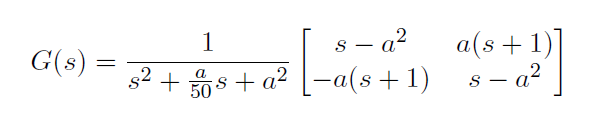

These dynamics model the motion of a cylindrical satellite spinning at constant rate Ω about the z-axis with a = (1 − Izz/Ixx)Ω. The controls affect the spin rates about x and y; as a becomes large, the system becomes increasingly sensitive to uncertainty. Assume a = 100 throughout.

(a) Assuming multiplicative output uncertainty of WI(s) = 20s+10/s+100 in the configuration shown and a performance weight of WP (s) = 0.5s+20/s+0.2 * I2×2, design a controller using the command mixsyn. Plot the achieved sensitivity function. Check whether you met your RP/RS goals.

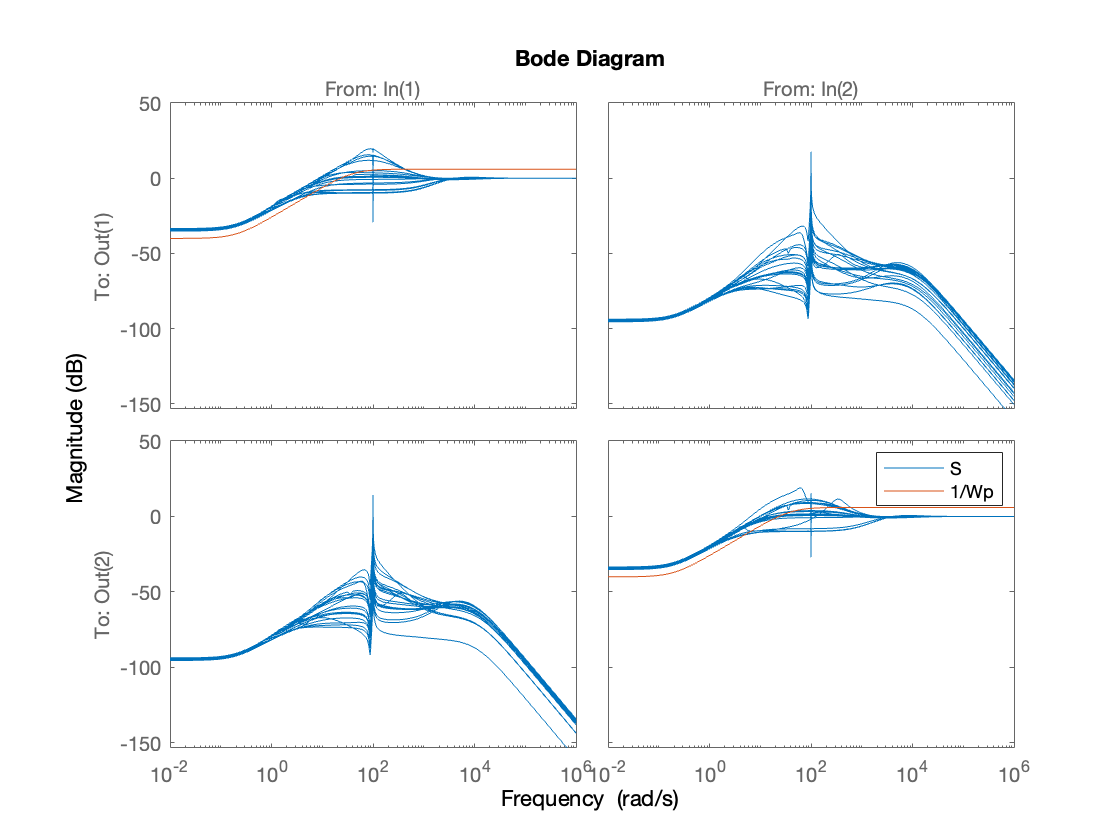

s = tf('s');
a = 100;
G = 1/(s^2+(a/50)*s+a^2) * [s-a^2 a*(s+1); -a*(s+1) s-a^2];
WI = (20*s+10)/(s+100) * eye(2);
Wp = (0.5*s+20)/(s+0.2) * eye(2);
[K,CL,GAM] = mixsyn(G,Wp,[],WI); 
delta1 = ultidyn('delta1',[1,1]);
delta2 = ultidyn('delta2',[1,1]);
delta = [delta1 0; 0 delta2];
G_hat = (eye(2)+delta*WI) * G; %structured uncertainty
S = 1/(eye(2)+G_hat*K);
%T = 1-S;
bodemag(S, 1/Wp)
legend("S","1/Wp")

Check RS

[STABMARG,WCU] = robstab(S);
mu = 1/STABMARG.LowerBound

mu = 1.8599

Check RP

[perfmarg,WCU] = robustperf(Wp*S);
mu = 1/perfmarg.LowerBound

mu = 2.7252

# Q1b

Assuming the same uncertainty model, design a controller using μ synthesis. Plot the achieved sensitivity function, check whether RP / RS are met, and compare the results with the H∞ design.

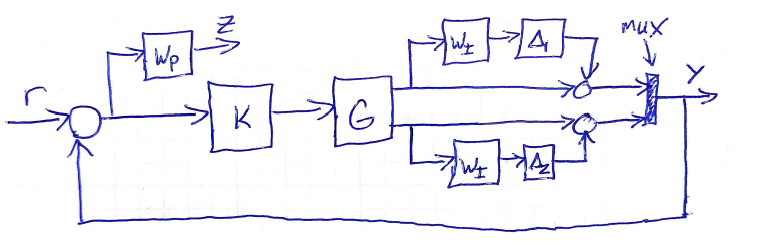

**Musyn design**

%build musyn system
delta1 = ultidyn('delta1',[1,1]);
delta2 = ultidyn('delta2',[1,1]);
G_hat = (eye(2)+[delta1 0;0 delta2]*WI) * G; %structured uncertainty
%need include uncertainty
systemnames = 'G_hat Wp'; %Block name only

Now we have to define the inputs and outputs to the system by giving values to *inputvar* and *outputvar*.

inputvar = '[r{2};u{2}]';
outputvar = '[Wp;r-G_hat]'; %Strangely, the system outputs are just the name

Here the variables are partitioned as before, i.e. the input variables are listed as $[w ,u]^T$.  Now we need to give the inputs to each system.

input_to_G_hat = '[u]';
input_to_Wp = '[r-G_hat]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
Pmu = sysic;
[Kmu,CLP,mu_mu] = musyn(Pmu,2,2);  %Same usage as Hinfsyn



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           2.717        2.711        2.734            12
    2           2.589        2.589        2.614            20
    3           2.589        2.588        2.588            20
    4            2.59        2.589        2.591            20

Best achieved robust performance: 2.59



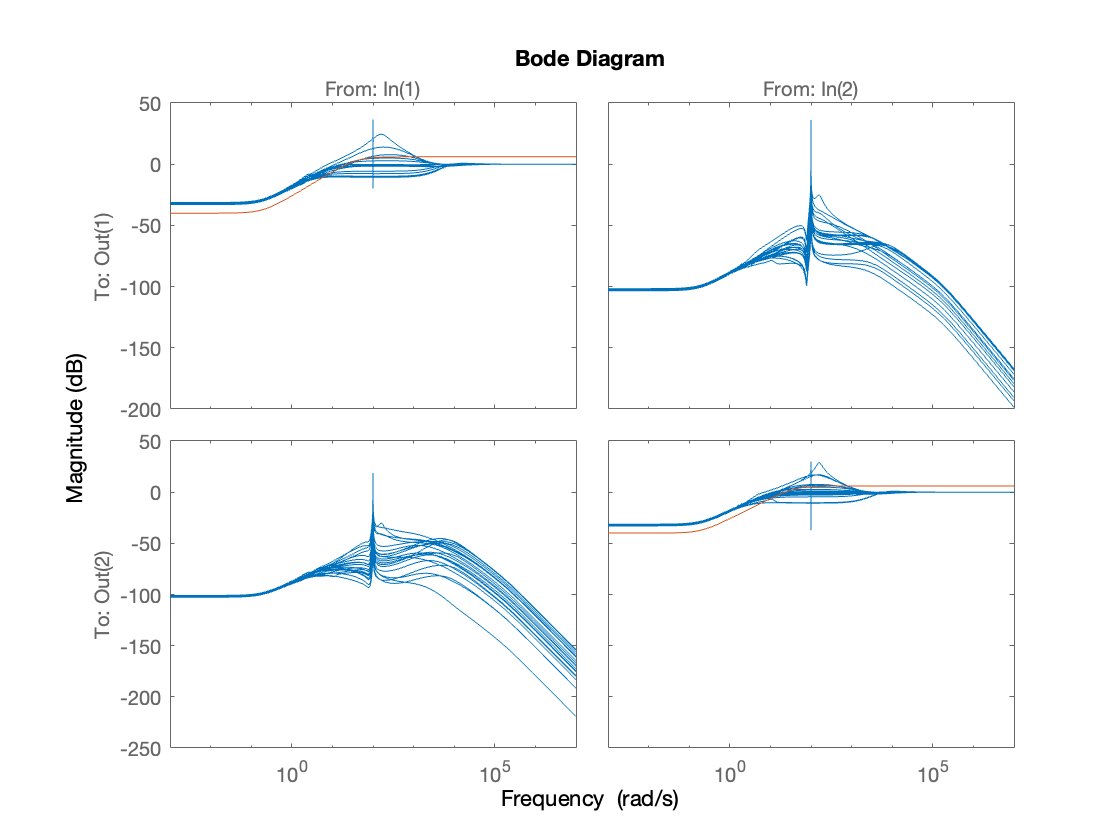

Smu =inv(eye(2)+G_hat*Kmu);
bodemag(Smu,1/Wp)

%Robust stabilty 
[STABMARG,WCU] = robstab(Smu);
mu_mu_stab = 1/STABMARG.LowerBound

mu_mu_stab = 2.0993

%robust performance
N_mu = lft(Pmu,Kmu);
perfmarg_mu = robustperf(N_mu);
mu_mu_perf = 1/perfmarg_mu.LowerBound

mu_mu_perf = 2.5879

# Q2C

(c) Consider the plant model

G(s) = $\frac{1}{75s+1}$$\left\lbrack \begin{array}{cc}
-87\ldotp 8 & 1\ldotp 4\\
-108\ldotp 2 & -1\ldotp 4
\end{array}\right\rbrack$

which is ill-conditioned with γ(G) = 70.8 at all frequencies. With an inverse-based controller K(s) =${\frac{0\ldotp 7}{s}G}^{-1} \left(s\right)$and uncertainty and performance weights WI = s+0.2/0.5s+1 and WP = s/2+0.05/s, compute μ for RP with both diagonal and full-block input uncertainty

s = tf("s");
G = (1/(75*s+1)) * [-87.8 1.4; -108.2 -1.4];
WI = (s+0.2)/(0.5*s+1) * eye(2);
epsilon = 1e-6;
WP = (s/2+0.05)/(s+epsilon) * eye(2);
K = (0.7/s)*inv(G);
delta1 = ultidyn('delta1',[1,1]);
delta2 = ultidyn('delta2',[1,1]);
delta_diag = [delta1 0; 0 delta2];
delta_full = ultidyn('delta_full',[2,2]);
G_hat_full = G*(eye(2)+delta_full*WI); %unstructured uncertainty
G_hat_diag = G*(eye(2)+delta_diag*WI); %structured uncertainty
%need include uncertainty
S_full = inv(eye(2) + G_hat_full * K);
S_diag = inv(eye(2) + G_hat_diag * K);
% bodemag(Smu,1/Wp)

systemnames = 'G_hat_full WP'; %Block name only
inputvar = '[r{2};u{2}]';
outputvar = '[WP;r-G_hat_full]'; %Strangely, the system outputs are just the name
input_to_G_hat_full = '[u]';
input_to_WP = '[r-G_hat_full]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
Pmu_full = sysic;
N_full = lft(Pmu_full, K);
perfmarg_full = robustperf(N_full);
mu_full = 1/perfmarg_full.LowerBound

mu_full = 4.1097

systemnames = 'G_hat_diag WP'; %Block name only
inputvar = '[r{2};u{2}]';
outputvar = '[WP;r-G_hat_diag]'; %Strangely, the system outputs are just the name
input_to_G_hat_diag = '[u]';
input_to_WP = '[r-G_hat_diag]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
Pmu_diag = sysic;
N_diag = lft(Pmu_diag, K);
perfmarg_diag = robustperf(N_diag);
mu_diag = 1/perfmarg_diag.LowerBound

mu_diag = 0.9669

# Q3a

(a) Write your own function to compute the ∞-norm of an arbitrary system (assumed in transfer function matrix form). Test your performance on the system

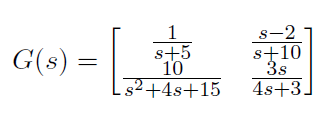

Method 1: Bi-section

s = tf("s");
G = [1/(s+5) (s-2)/(s+10);10/(s^2+4*s+15) 3*s/(4*s+3)];
state_space = ss(G);
A = state_space.A;
B = state_space.B;
C = state_space.C;
D = state_space.D;
I = eye(size(D));
R = gam^2 * I - D'*D;
g_low = 0;
g_high = 1000;
g_try = g_high;
g_new = 1/2 * (g_high + g_low);
while(abs(g_new - g_try)>0.001)
    g_try = g_new;
    R = g_try^2 * eye(size(D)) - D'*D;
    H = [A+B*inv(R)*D'*C B*inv(R)*B';-C'*(I+D*inv(R)*D')*C -(A+B*inv(R)*D'*C)'];
    r = min(abs(real(eig(H))));
    if r>0.001
        g_high = g_try;
    else
        g_low = g_try;
    end
    g_new = 1/2 * (g_high + g_low);
end

Method 2: iteration by 0.01 increment for gamma.

% gam = 0.01; 
% I = eye(size(D));
% R = gam^2 * I - D'*D;
% H = [A (1/gam^2)*B*B';-C'*C -A'];
% H = [A+B*inv(R)*D'*C B*inv(R)*B';-C'*(I+D*inv(R)*D')*C -(A+B*inv(R)*D'*C)'];
% eigen = eig(H);
% no_real_part = (round(real(eigen),5) == 0) & (imag(eigen) ~= 0);
% while sum(no_real_part)>0
%     gam = gam+0.01; % eigen value has pure imaginary number
%     R = gam^2 * I - D'*D;
%     H = [A+B*inv(R)*D'*C B*inv(R)*B';-C'*(I+D*inv(R)*D')*C -(A+B*inv(R)*D'*C)'];
%     eigen = eig(H);
%     no_real_part = (round(real(eigen),5) == 0) & (imag(eigen) ~= 0);
% end
%norm_inf = gam

Produce norm

norm_inf = g_new

norm_inf = 1.2503

norm_inf = norm(G,"inf")

norm_inf = 1.2500

(b) Repeat Part b for the 2-norm. Because the 2-norm is finite only for strictly proper systems, test it on

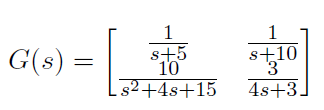

or some other suitably modified version of the plant from Part b.

G = [1/(s+5) 1/(s+10);10/(s^2+4*s+15) 3/(4*s+3)];
state_space = ss(G);
A = state_space.A;
B = state_space.B;
C = state_space.C;
Q = gram(state_space,'o');
norm_2 = sqrt(trace(B'*Q*B))

norm_2 = 1.1655

norm_2 = norm(G, 2)

norm_2 = 1.1655